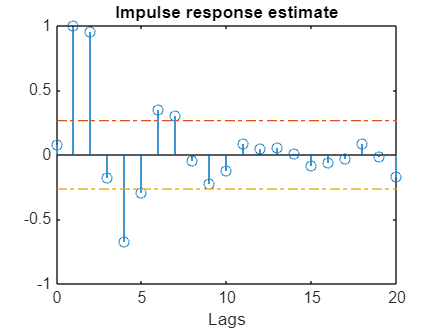

A = [1 -0.5 0.7];
B = [0 1 0.5];
th0 = poly2th(A, B);
u = idinput(500,'rbs');
y = idsim([u, randn(500, 1)], th0);
z = [y u];
ir = cra(z);

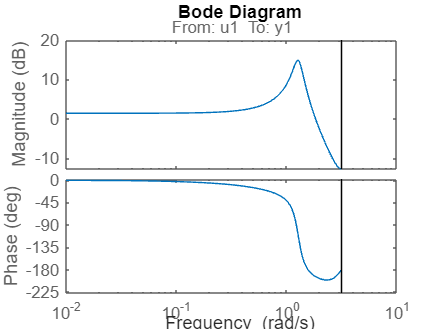

A = [1 -0.5 0.7];
B = [0 1 0.5];
m0 = idpoly(A, B);
u = iddata([], idinput(300, 'rbs')); 
e = iddata([], idinput(300));
y = sim(m0,[u e]);
z = [y u];
m = arx(z, [2 2 1]);
bode(m);

Discrete-time IDPOLY model: A(q)y(t) = B(q)u(t) + e(t)

A(q) = 1 - 0.4631 g^-1 + 0.6884 q^-2

B(q) = 1.039 q^-1 + 0.5507 q^-2